% Pendulum parameters
L = 1;               % Length of pendulum (meters)
g = 9.81;            % Gravity (m/s^2)
theta0 = pi/2;       % Initial angle (radians)

% Time settings
dt = 0.05;           % Time step
T = 10;              % Total time
t = 0:dt:T;          % Time vector

% Angular frequency for small angle approx.
omega = sqrt(g / L);
theta = theta0 * cos(omega * t);  % Angle as a function of time
x = L * sin(theta);  % Horizontal position
y = -L * cos(theta); % Vertical positionfigure;
% Create new figure window
axis equal;
axis([-1.2 1.2 -1.2 0.2]); % Set axis limits
hold on;

% Draw pivot
plot(0, 0, 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'k');

% Initialize pendulum line and bob
pendulumLine = line([0 x(1)], [0 y(1)], 'LineWidth', 2);%'Color','k'
bob = plot(x(1), y(1), 'ro', 'MarkerSize', 30, 'MarkerFaceColor', 'r');

for i = 1:length(t)
    % Update pendulum line
    set(pendulumLine, 'XData', [0 x(i)], 'YData', [0 y(i)]);
    set(bob, 'XData', x(i), 'YData', y(i));
    
    drawnow;       % Update figure
    pause(dt);     % Wait for next frame
end


## ODE5

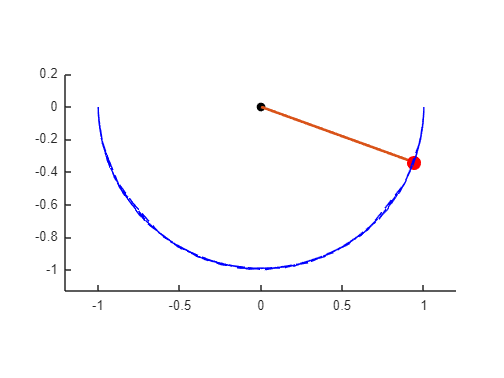

% Parameters
g = 9.81;      % Gravity
L = 1;         % Length of pendulum
theta0 = pi/2; % Initial angle (radians)
omega0 = 0;    % Initial angular velocity

% Time span
tspan = [0 5];

% ODE function for pendulum: d2theta/dt2 = -(g/L) * sin(theta)
pendulumODE = @(t, y) [y(2); - (g/L) * sin(y(1))];

% Solve ODE
[t, y] = ode45(pendulumODE, tspan, [theta0, omega0]);

% Extract angle
theta = y(:, 1);
x = L * sin(theta);
y = -L * cos(theta);

% Animation
figure;
axis equal;
axis([-1.2 1.2 -1.2 0.2]);
hold on;
plot(0, 0, 'ko', 'MarkerFaceColor', 'k'); % pivot

% Initialize objects
pendulumLine = line([0 x(1)], [0 y(1)], 'LineWidth', 2);
bob = plot(x(1), y(1), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
trail = animatedline('LineStyle','--','Color', 'b');

for i = 1:length(t)
    % Update pendulum position
    set(pendulumLine, 'XData', [0 x(i)], 'YData', [0 y(i)]);
    set(bob, 'XData', x(i), 'YData', y(i));
    addpoints(trail, x(i), y(i)); % Add to trail

    drawnow;
    pause(0.01);
end

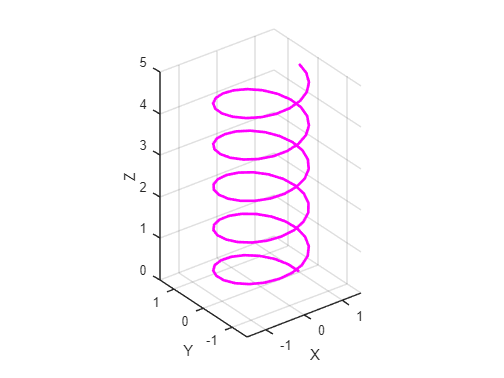

% Time vector
t = linspace(0, 10*pi, 100);
x = cos(t);
y = sin(t);
z = t / (2*pi); % slowly rising spiral

% Initialize 3D plot
figure;
ax = axes;
axis equal;
grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
xlim([-1.5 1.5]);
ylim([-1.5 1.5]);
zlim([0 max(z)]);
view(3);

% Animated line in 3D
spiralTrail = animatedline('Color', 'm', 'LineWidth', 2);

for i = 1:length(t)
    addpoints(spiralTrail, x(i), y(i), z(i));
    drawnow;
    pause(0.01);
end

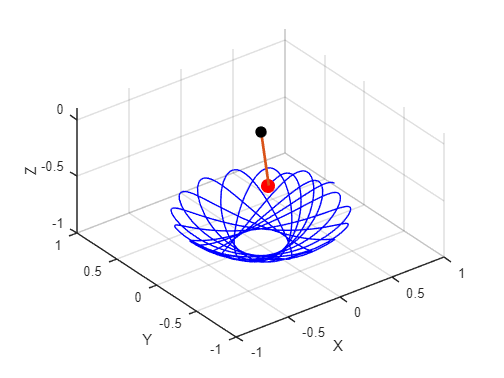

% Parameters
g = 9.81;      % gravity
L = 1;         % pendulum length (meters)
theta0 = pi/4; % initial elevation angle from vertical
phi0 = 0;      % initial azimuth angle
dtheta0 = 0;   % initial elevation angular velocity
dphi0 = 1;     % initial azimuth angular velocity (creates circular motion)

% Time
tspan = [0 20];

% State vector: [theta; dtheta; phi; dphi]
y0 = [theta0; dtheta0; phi0; dphi0];

% ODEs for spherical pendulum (simplified)
pendulum3D = @(t, y) [
    y(2); % dtheta
    sin(y(1)) * cos(y(1)) * y(4)^2 - (g/L) * sin(y(1)); % d2theta
    y(4); % dphi
    -2 * y(2) * y(4) * cot(y(1)) % d2phi (simplified)
];

% Solve ODE
[t, Y] = ode45(pendulum3D, tspan, y0);

% Extract angles
theta = Y(:,1);
phi = Y(:,3);

% Convert to Cartesian coordinates
x = L * sin(theta) .* cos(phi);
y = L * sin(theta) .* sin(phi);
z = -L * cos(theta);

% Animation
figure;
axis equal;
grid on;
xlabel('X'); ylabel('Y'); zlabel('Z');
xlim([-L L]); ylim([-L L]); zlim([-L 0.1]);
view(3);
hold on;

% Plot pivot point
plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

% Initialize line and bob
line3D = line([0 x(1)], [0 y(1)], [0 z(1)], 'LineWidth', 2);
bob3D = plot3(x(1), y(1), z(1), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
trail3D = animatedline('Color', 'b', 'LineWidth', 1);

% Animate
for i = 1:length(t)
    % Update pendulum
    set(line3D, 'XData', [0 x(i)], 'YData', [0 y(i)], 'ZData', [0 z(i)]);
    set(bob3D, 'XData', x(i), 'YData', y(i), 'ZData', z(i));
    addpoints(trail3D, x(i), y(i), z(i));
    
    drawnow;
    pause(0.01);
end